hold on
grid on


V_1_1 = [32.91
32.62
31.67
31.22
30.79
30.6
30.32
30.46
30.5
30.5
30.52
30.5];

I_1_1 = 1/24*[14
21
40
50
60
70
80
90
100
110
115
120
];

V_1_2 = [30.52
30.51
30.51
30.45
30.29
30.57
30.76
31.16
31.65
32.61
34.08
35
35.17
];

I_1_2 = 1/24*[
115
110
100
90
80
70
60
50
40
31
21
14
12
];

scatter( I_1_1,V_1_1, "Marker","+", "MarkerEdgeColor",'r');
scatter( I_1_2, V_1_2, "Marker","+","MarkerEdgeColor", "b");
V_1 = V_1_2(9:13);
I_1 = I_1_2(9:13);

xlim([0;5])
ylim([30;36])
coeff_1 = polyfit(I_1,V_1, 1)

coeff_1 =    -3.1101   36.7603


y1 = 0;
xi = min(0.3):0.1:max(1.8)

xi =     0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000


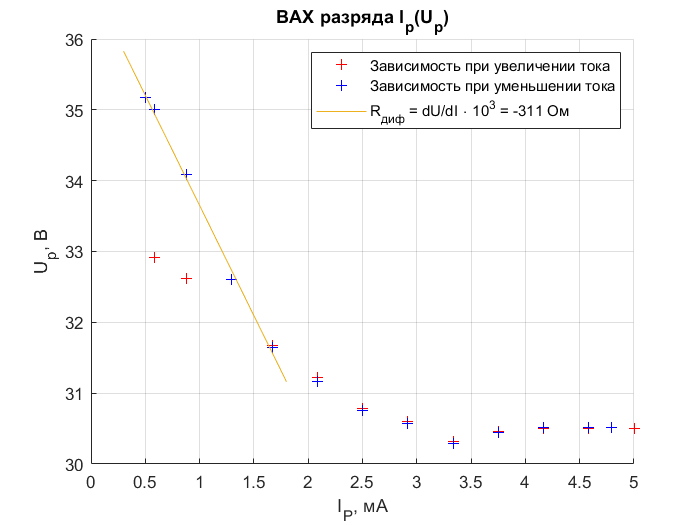

for k=0:1
    y1 = y1 + coeff_1(1-k+1) * xi.^k;
end
gr_1 = plot(xi, y1); 
title("ВАХ разряда I_p(U_p)")
xlabel('I_P, мА')
ylabel('U_p, В')
legend("Зависимость при увеличении тока",'Зависимость при уменьшении тока', 'R_{диф} = dU/dI \cdot 10^3 = -311 Ом ')
hold off;